# Modeling density of bird migration

This current script present a spatio-temporal model of the nightly migration of bird over europe based on measurement of radar. 

The model decomposes a power transform of the row signal of migration, *Z,  *into 3 signals:  a daily amplitude *A, *a temporally stationary trend and a residus *R:*


$${\textrm{Z(}t,\textrm{s)}}^a =t\left(s\right)+A\left(t_{\textrm{day}} ,\mathit{\mathbf{s}}\right)+c\left(t_{\textrm{hr}} ,p\right)+R\left(t,\mathit{\mathbf{s}}\right)$$


- The trend *t* is is used in order to make the amplitude spatially stationary. The trend is a fitted plane.

- The amplitude is average bird density during a night at each location, such that it becomes a daily spatio-temporal  signal. A polynomial curve c is fit together with the amplitude to take into acount the variation during a night. The time is normalized according to sunset (-1) and sunrise (1). 

- The curve

- The residus R is the unexplained signal of this daily amplitude. It also shows a spatio-temporal correlation.

The fitted curve c is simply fitted together with the amplitude at all the radar and all night. The ammplitude and residus are close to normal distributed so that a normla score is acceptable. The ampli.cov.parmriance parameter of both variable are fitted on the data with a Gneiting model. Then, using kriging, we can simulate the spatial temporal model. Validation is performed by removing a radar, and simulating it based on the others one. 

## 1. Import and create data

clear all; load('./data/dc_corr.mat'); load coastlines; addpath('functions/'); warning('off')

Convert the volumetric densit to a surface densisty (`denss`)

for i=1:numel(dc)
    tmp=diff(double([0 max(0, (1:dc(i).levels).*dc(i).interval - dc(i).height )]))/1000;
    dc(i).denss = dc(i).dens*tmp';
    dc(i).scoret = datenum(dc(i).time'-mean([dc(i).sunrise;dc(i).sunset])) ./ datenum(dc(i).sunrise-dc(i).sunset)*2;
end

Create the data structure `data`

dens_lim = 0.002;
data=[];
uniqueDate = round(datenum(datetime(start_date-1:end_date-1)));
for i=1:numel(dc)
    id = dc(i).scoret(:)>=-1 & dc(i).scoret(:)<=1 & dc(i).denss>dens_lim;
    d=table();
    d.dens=dc(i).denss(id);
    d.scoret = dc(i).scoret(id)';
    d.i_r=i*ones(sum(id),1);
    d.lat=dc(i).lat*ones(sum(id),1);
    d.lon=dc(i).lon*ones(sum(id),1);
    d.time = datenum(dc(i).time(id));
    d.duration = dc(i).etime(id)-dc(i).stime(id);
    tmp = round(datenum(dc(i).sunrise(id)))';
    [~,id]=ismember(tmp,uniqueDate);
    d.dateradar = sub2ind([numel(dc) numel(uniqueDate)],repmat(i,numel(tmp),1),id);
    % filter by day with less than 10% of data present
    out = [uniqueDate',histc(tmp,uniqueDate')];
    tmp2 = ~ismember(tmp,out(0.1*max(out(:,2))>out(:,2),1));
    data = [data ; d(tmp2,:) ];
end

clear d dens_lim tmp

## 2. Transformation of data

The row data of density present a very scew histogram

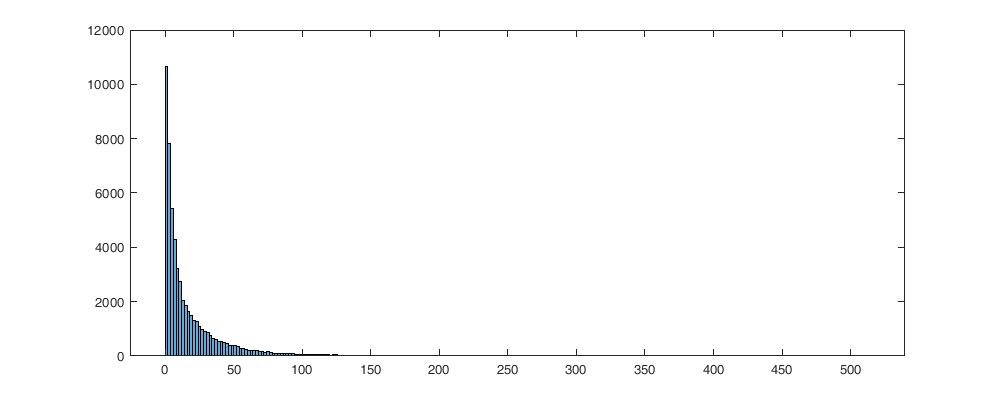

figure('position',[0 0 1000 400]); histogram(data.dens)

Several transformation can be tried. 

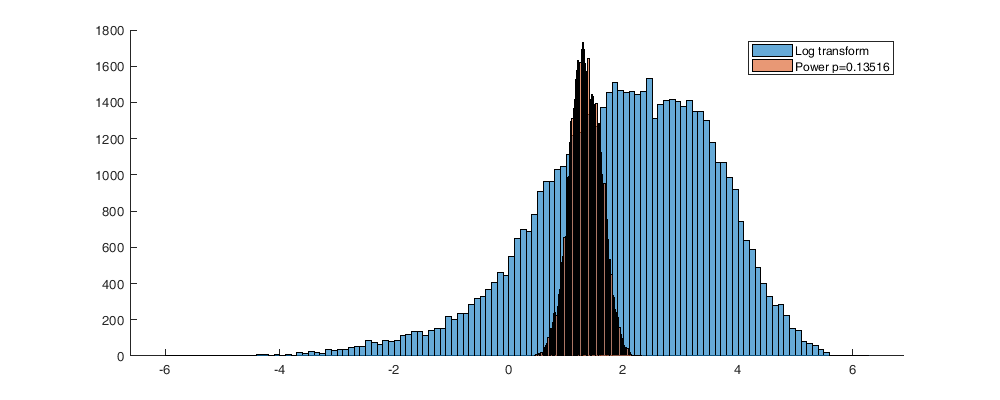

pow_a = fminsearch(@(i) kstestmin(i,data.dens) ,1/8);

figure('position',[0 0 1000 400]); hold on;
histogram(log(data.dens))
histogram(data.dens.^pow_a)
legend('Log transform',['Power p=' num2str(pow_a)])

data.denstrans = data.dens.^pow_a;

## 3. Amplitude, trend and cuve fitting

This section's purpuse is to find the value of *A* and paramaters of the polynomial *p* which fit best the data. We first find them seperatively and then perform a min-search of the equation combined.


$${\text{Z(}t,\text{s)}}^{\frac{1}{8}} =A\left(t_{\text{day}} ,\mathit{\mathbf{s}}\right)-t\left(\mathit{\mathbf{s}}\right)+C\left(t_{\text{hr}} ,p\right)$$


Initialize *t* by simply finding the average of  each radar

S=zeros(numel(dc), 1);
for i=1:numel(dc)
    S(i)=mean(data.denstrans(data.i_r==i));
end
trend.p0=[ [dc.lat]' ones(numel(dc),1)] \ S;
trend.t0 = ([dc.lat]'*trend.p0(1)+trend.p0(2));

Initialize A by simply finding the average of the night for each radar

ampli.A0=nan(numel(dc), numel(uniqueDate));
for i=1:numel(ampli.A0)
    ampli.A0(i)=mean(data.denstrans(data.dateradar==i));
end
ampli.A0=ampli.A0-repmat(trend.t0,1,numel(uniqueDate));

Intialize the polyfit parameter by the residual of A for all radars. 

curve.nb_poly=6;
curve.p0 = polyfit(data.scoret,data.denstrans-trend.t0(data.i_r)-ampli.A0(data.dateradar),curve.nb_poly);

Performing an optimazation of the amplitude and polyfit parameter combined. 

rmse = @(x) nansum( ( pred3(x,numel(dc),numel(uniqueDate),curve.nb_poly,data,dc)  - data.denstrans ).^2 );
x = fminsearch(rmse,[trend.p0(:);ampli.A0(:);curve.p0(:)],optimset('MaxFunEvals',1000));

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 430.284884 



trend.p = x(1:2);
ampli.A = reshape(x(2+(1:numel(dc)*numel(uniqueDate))),numel(dc),numel(uniqueDate));
curve.p = x(end-curve.nb_poly:end);

Figure

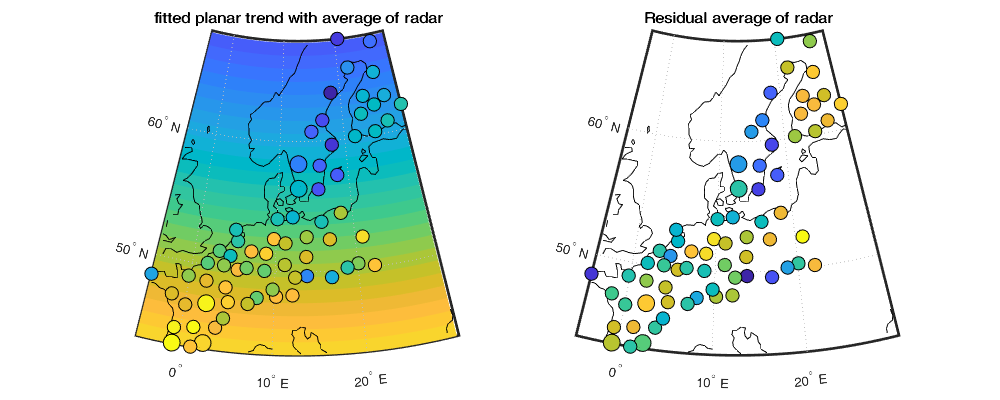

trend.t = ([dc.lat]'*trend.p(1)+trend.p(2));

figure('position',[0 0 1000 400]);  
subplot(1,2,1); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
[LAT,LON] = meshgrid(min([dc.lat]):max([dc.lat]),min([dc.lon]):max([dc.lon]));
surfm(LAT,LON,LAT*trend.p(1)+trend.p(2))
plotm(coastlat, coastlon,'k')
scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,S,'filled','MarkerEdgeColor','k'); title('fitted planar trend with average of radar'); 
subplot(1,2,2); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
plotm(coastlat, coastlon,'k')
scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,S-trend.t,'filled','MarkerEdgeColor','k'); title('Residual average of radar');

The average of each radar during the study period shows a strong NS increase. This is expected as the migrant tion.... 

The residual shows more the coridor of migration with lower migration density along the FR-NL coast, and along the Alps. Another strange effect is the drastic change between Sweden and Finland. Why? 

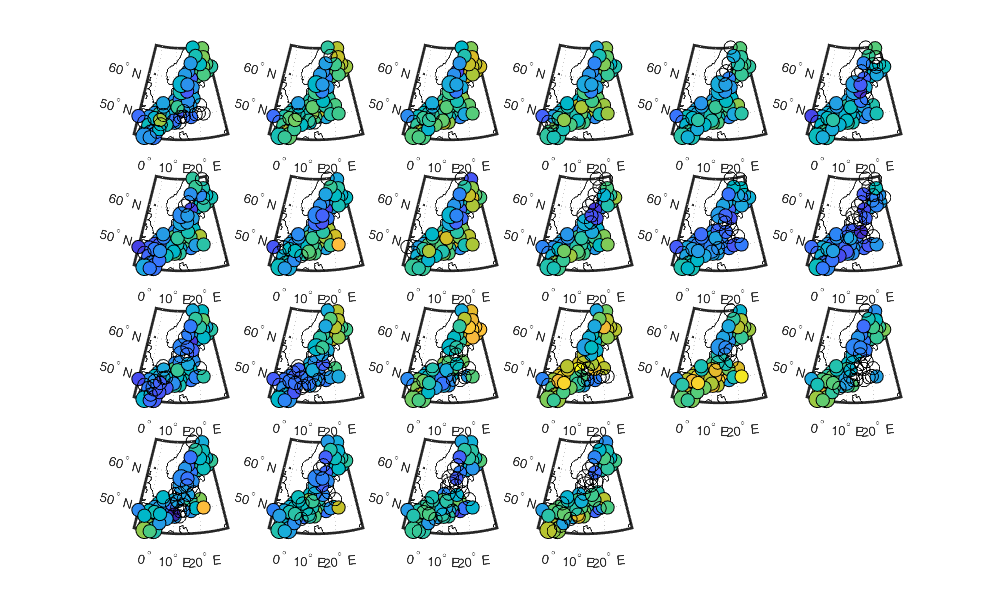

figure('position',[0 0 1000 600]);  c_caxis=[min(ampli.A(:)) max(ampli.A(:))];
for i = 1:numel(uniqueDate)
    subplot(4,6,i); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  plotm(coastlat, coastlon,'k')
    scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,ampli.A(:,i),'filled','MarkerEdgeColor','k');
    caxis(c_caxis);
end

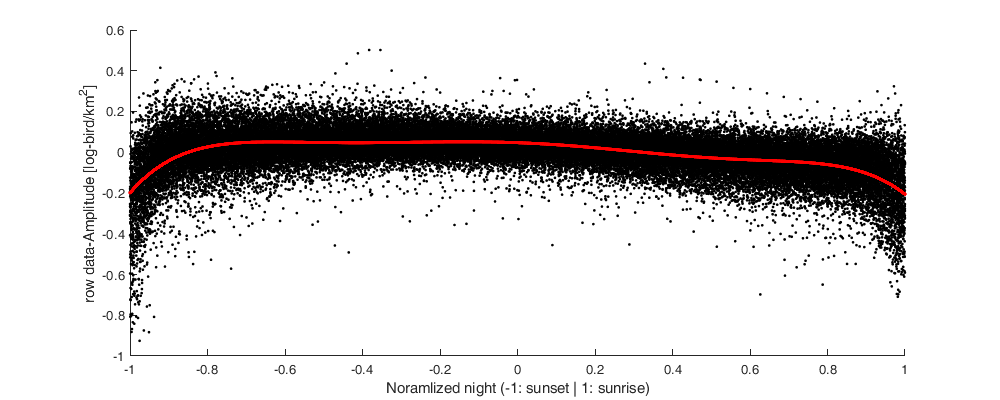

figure('position',[0 0 1000 400]); hold on; plot(data.scoret,data.denstrans-trend.t(data.i_r)-ampli.A(data.dateradar),'.k'); plot(data.scoret, polyval( curve.p, data.scoret ),'.r'); ylim([-1 .6])
xlabel('Noramlized night (-1: sunset | 1: sunrise)'); ylabel('row data-Amplitude [log-bird/km^2]')

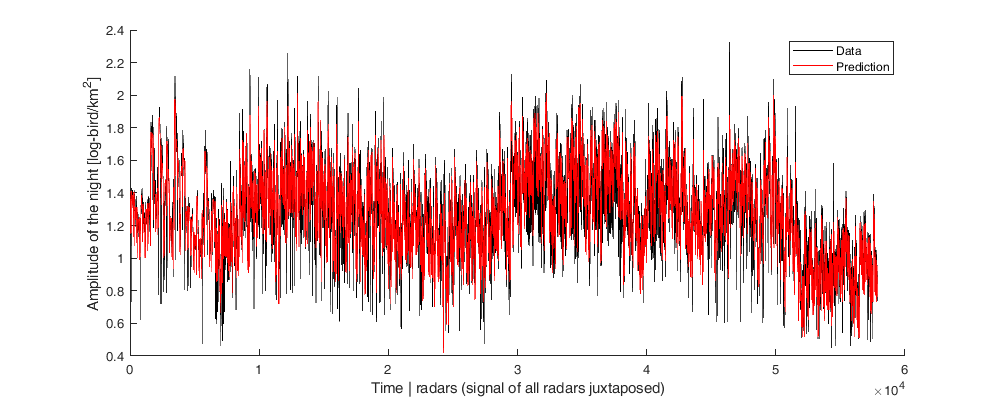

figure('position',[0 0 1000 400]); hold on; plot(data.denstrans,'k'); plot(pred3([trend.p(:);ampli.A(:);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc),'r'); 
xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [log-bird/km^2]'); legend('Data','Prediction')

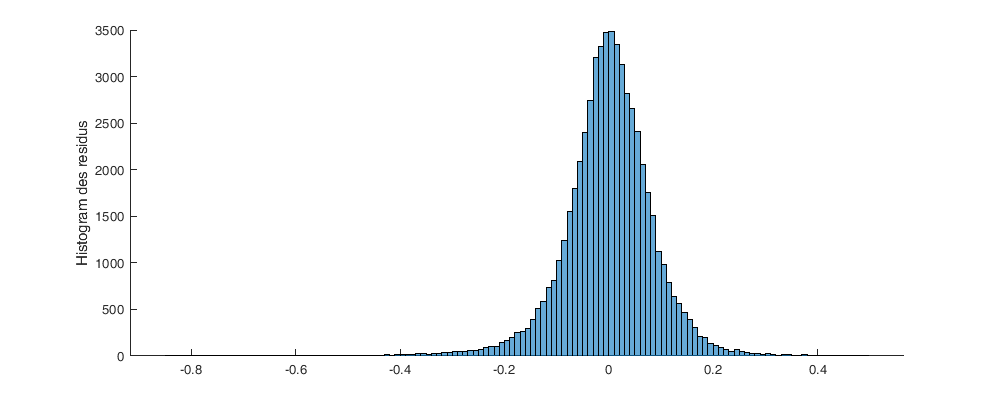

figure('position',[0 0 1000 400]); hold on; ylabel('Histogram des residus')
histogram(data.denstrans-pred3([trend.p(:);ampli.A(:);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc)); 

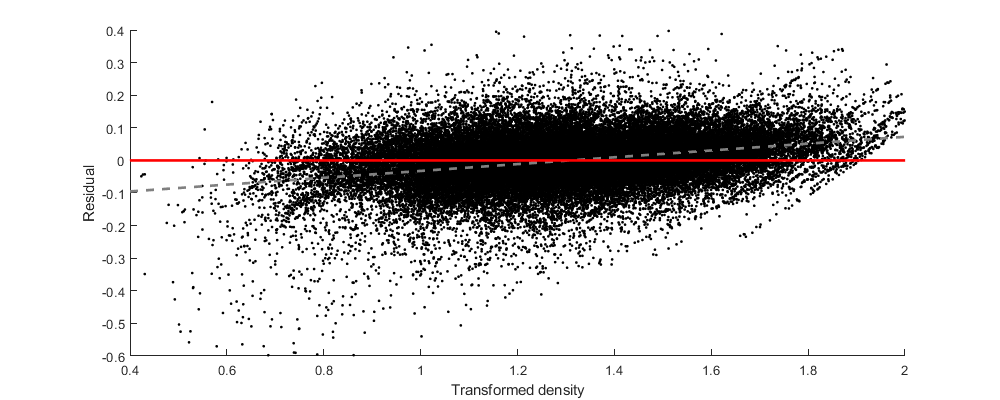

figure('position',[0 0 1000 400]); hold on; ylabel('Residual'); xlabel('Transformed density')
scatter(data.denstrans,data.denstrans-pred3([trend.p(:);ampli.A(:);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc),'.k'); 
coeffs = polyfit(data.denstrans,data.denstrans-pred3([trend.p(:);ampli.A(:);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc), 1);
plot( [.2 2.2],coeffs*[ .2 2.2; 1 1],'--','Color',[.5 .5 .5],'LineWidth',2)
plot([.2 2.2],[0 0],'r','LineWidth',2); axis([.4 2 -.6 .4])

## 4. Kriging Amplitude

## 4.1 Normal Score

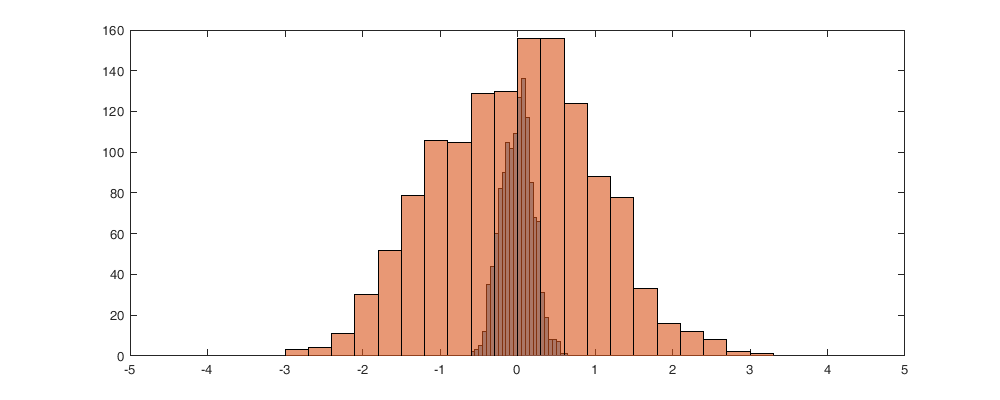

% ampli.ns = nscore(ampli.A(:));
% ampli.An = ampli.ns.forward(ampli.A);
%ampli.ns.mu = nanmean(ampli.A(:)); = 0
ampli.ns.std = nanstd(ampli.A(:));
ampli.An = ampli.A/ampli.ns.std;

figure('position',[0 0 1000 400]); hold on; histogram(ampli.A) ; histogram(ampli.An); box on;xlim([-5 5])

Buliding the distance

Dtime_sf=squareform(pdist(repelem(uniqueDate',numel(dc),1)));
Ddist_sf=squareform(pdist(repmat([[dc.lat]' [dc.lon]'], numel(uniqueDate),1),@lldistkm));

ampli.isnanA=isnan(ampli.An);
ampli.Dtime_sf=Dtime_sf(~ampli.isnanA,~ampli.isnanA);
ampli.Ddist_sf=Ddist_sf(~ampli.isnanA,~ampli.isnanA);
ampli.Anl=ampli.An(~ampli.isnanA)-nanmean(ampli.An(:));

## 4.2 Empirical ampli.cov.parmriogram

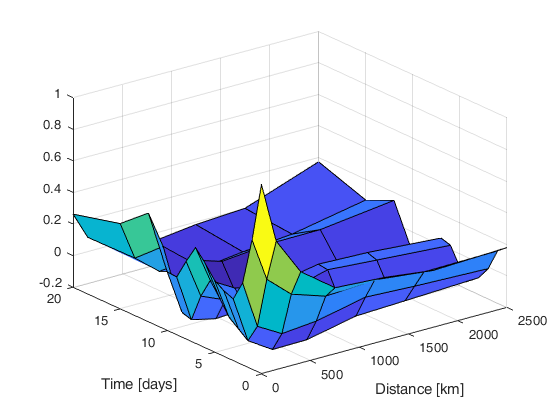

ampli.cov.emp = bsxfun(@times, ampli.Anl', ampli.Anl);

ampli.cov.d=[0 1 300 500 1000 1500 2000 3000];
ampli.cov.t=[0 1 2 3 4 5 6 7 8 9 10 12 15 20 30]; 
[ampli.cov.D,ampli.cov.T] = meshgrid(ampli.cov.d(1:end-1)+diff(ampli.cov.d)/2,ampli.cov.t(1:end-1));
ampli.cov.emp_grid=nan(size(ampli.cov.D));
for i_t=1:numel(ampli.cov.t)-1
    for i_d=1:numel(ampli.cov.d)-1
        id = ampli.Dtime_sf>=ampli.cov.t(i_t) & ampli.Dtime_sf<ampli.cov.t(i_t+1) & ampli.Ddist_sf>=ampli.cov.d(i_d) & ampli.Ddist_sf<ampli.cov.d(i_d+1);
        ampli.cov.emp_grid(i_t,i_d) = mean( ampli.cov.emp(id) );
    end
end
figure;surf(ampli.cov.D,ampli.cov.T,ampli.cov.emp_grid); xlabel('Distance [km]'); ylabel('Time [days]')

## 4.3 Variogram fitting

The variogram fitted is composed of a nugget and Gneiting model. The data are filtered by a maximum distance and time and reduce the computational cost and overfitting long-distance/time lag. First a gloabl optimzer is used (multi-start) and then a local optimizer refine the result

Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );
Gneiting_fit = @(parm) parm(2).*Gneiting(ampli.cov.D(2:end),ampli.cov.T(2:end),parm(3),parm(4),parm(5),parm(6),parm(7));

ampli.cov.parm0 =[.5 .5 500 5 .5 .5 .5];
ampli.cov.parm_min=[0 0 0.0001 0 0 0 0 ]';
ampli.cov.parm_max=[nancov(ampli.Anl) nancov(ampli.Anl) 3000 10 1 1 1]';

rmse = @(parm) sum( ( (Gneiting_fit(parm) - ampli.cov.emp_grid(2:end)) ).^2 );
ampli.cov.parm = fmincon(rmse,ampli.cov.parm0,[],[],[],[],ampli.cov.parm_min,ampli.cov.parm_max,[]);% ,optimset('PlotFcn',@optimplotfval)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<stopping criteria 

ampli.cov.parm(1) = nancov(ampli.Anl)-ampli.cov.parm(2);
sprintf('%.3f ',ampli.cov.parm)

ans = '0.000 1.000 174.440 0.389 0.179 0.429 0.000 '

Figure

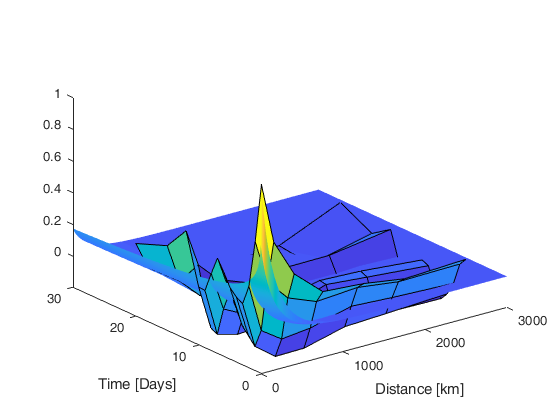

[tmpD,tmpT] = meshgrid(ampli.cov.d(1):1:ampli.cov.d(end),ampli.cov.t(1):0.1:ampli.cov.t(end));
tmpCOV=ampli.cov.parm(2).*Gneiting(tmpD(:), tmpT(:), ampli.cov.parm(3), ampli.cov.parm(4), ampli.cov.parm(5), ampli.cov.parm(6), ampli.cov.parm(7));
tmpCOV=reshape(tmpCOV,size(tmpD,1),size(tmpD,2));
tmpCOV(1)=tmpCOV(1)+ampli.cov.parm(1);
figure; hold on;
s=surf(tmpD,tmpT,tmpCOV);
surf(ampli.cov.D,ampli.cov.T,ampli.cov.emp_grid);  xlabel('Distance [km]'); ylabel('Time [Days]');
s.EdgeColor='none'; view(3)

## 4.4 Estimate Amplitude with kriging

ampli.cov.C = diag(repmat(ampli.cov.parm(1),size(ampli.Ddist_sf,1),1)) + ampli.cov.parm(2).*Gneiting(ampli.Ddist_sf,ampli.Dtime_sf, ampli.cov.parm(3), ampli.cov.parm(4), ampli.cov.parm(5), ampli.cov.parm(6), ampli.cov.parm(7));

[~,R] = meshgrid(uniqueDate,1:numel(dc));
R=R(~ampli.isnanA);

ampli.An_est=nan(size(ampli.Anl));
ampli.An_sig=nan(size(ampli.Anl));

for i=1:numel(dc)

    neigh=R~=i;
    sim=find(~neigh);
    %i_neigh(Dist_km_sf(i,:)<100)=false;
    
    for i_sim=1:numel(sim)
        lambda = ampli.cov.C(neigh,neigh)  \  ampli.cov.C(neigh,sim(i_sim));
        ampli.An_est(sim(i_sim)) =  lambda' * ampli.Anl(neigh);
        ampli.An_sig(sim(i_sim)) = sqrt(ampli.cov.parm(1) + ampli.cov.parm(2) - lambda' * ampli.cov.C(neigh,sim(i_sim)));
    end
end



Figure;

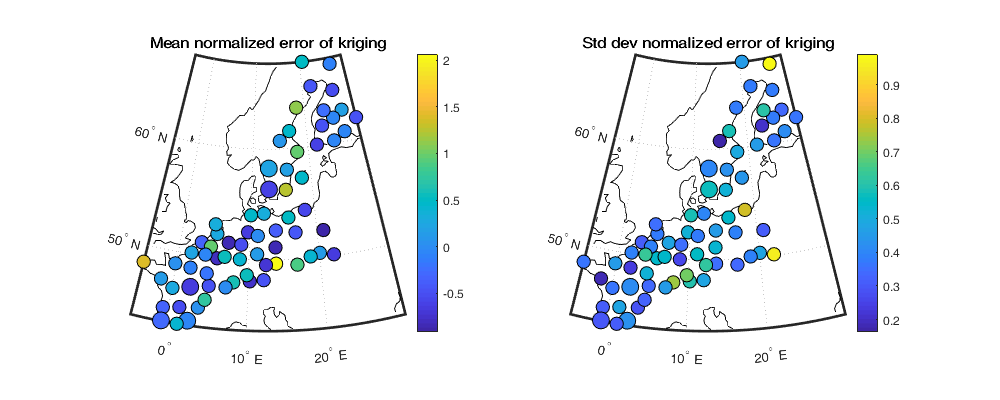

A_i_r =repmat((1:numel(dc))',1,22);
A_i_r=A_i_r(~ampli.isnanA);
for i_r=1:numel(dc)
    ampli_err_avg(i_r) = mean((ampli.An_est(A_i_r==i_r)-ampli.Anl(A_i_r==i_r))./ampli.An_sig(A_i_r==i_r));
    ampli_err_std(i_r) = std((ampli.An_est(A_i_r==i_r)-ampli.Anl(A_i_r==i_r))./ampli.An_sig(A_i_r==i_r));
end

figure('position',[0 0 1000 400]);  
subplot(1,2,1); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
plotm(coastlat, coastlon,'k')
scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,ampli_err_avg,'filled','MarkerEdgeColor','k'); title('Mean normalized error of kriging'); colorbar;
subplot(1,2,2); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
plotm(coastlat, coastlon,'k')
scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,ampli_err_std,'filled','MarkerEdgeColor','k'); title('Std dev normalized error of kriging'); colorbar;

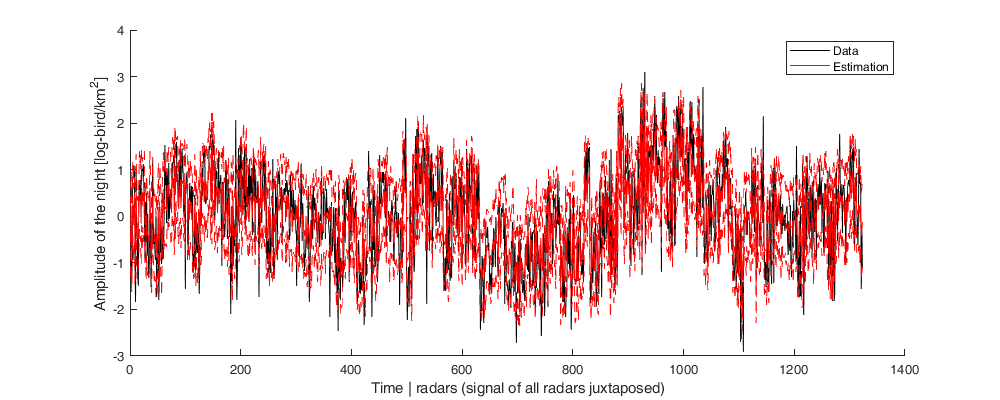

figure('position',[0 0 1000 400]); hold on;
plot(ampli.Anl,'k');
plot(ampli.An_est,'r')
plot(ampli.An_est-ampli.An_sig,'--r')
plot(ampli.An_est+ampli.An_sig,'--r')
xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [log-bird/km^2]'); legend('Data','Estimation')

## 4.5 Back-transform

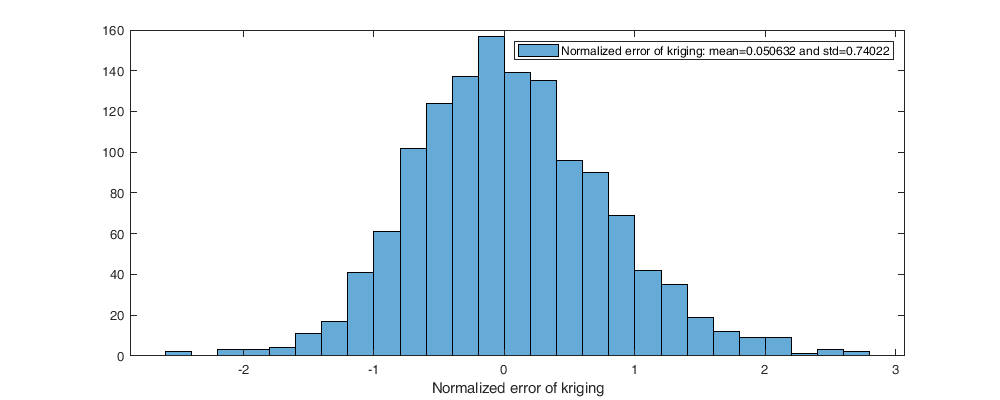

ampli.A_est= nan(size(ampli.A));
ampli.A_est(~ampli.isnanA) = ampli.An_est*ampli.ns.std;
ampli.A_sig = nan(size(ampli.A));
ampli.A_sig(~ampli.isnanA) = sqrt(ampli.An_sig.^2 * ampli.ns.std.^2);

%ampli.A_sig = nan(size(ampli.A,1),size(ampli.A,2),7);
%ampli.A_sig(~repmat(ampli.isnanA,1,1,7)) = ampli.ns.inverse( repmat(ampli.An_est,1,7) + bsxfun(@times,ampli.An_sig,(-3:3)) );

err_norm=(ampli.A_est-ampli.A)./ampli.A_sig;
err_norm=err_norm(~ampli.isnanA);
figure('position',[0 0 1000 400]); histogram(err_norm)
xlabel('Normalized error of kriging')
legend(['Normalized error of kriging: mean=' num2str(mean(err_norm)) ' and std=' num2str(std(err_norm))]);


c_caxis=[min(ampli.A(:)) max(ampli.A(:))];
figure('position',[0 0 1000 600]);
for i = 1:numel(uniqueDate)
    subplot(4,6,i); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  plotm(coastlat, coastlon,'k')
    scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,ampli.A(:,i),'filled','MarkerEdgeColor','k'); caxis(c_caxis)
end

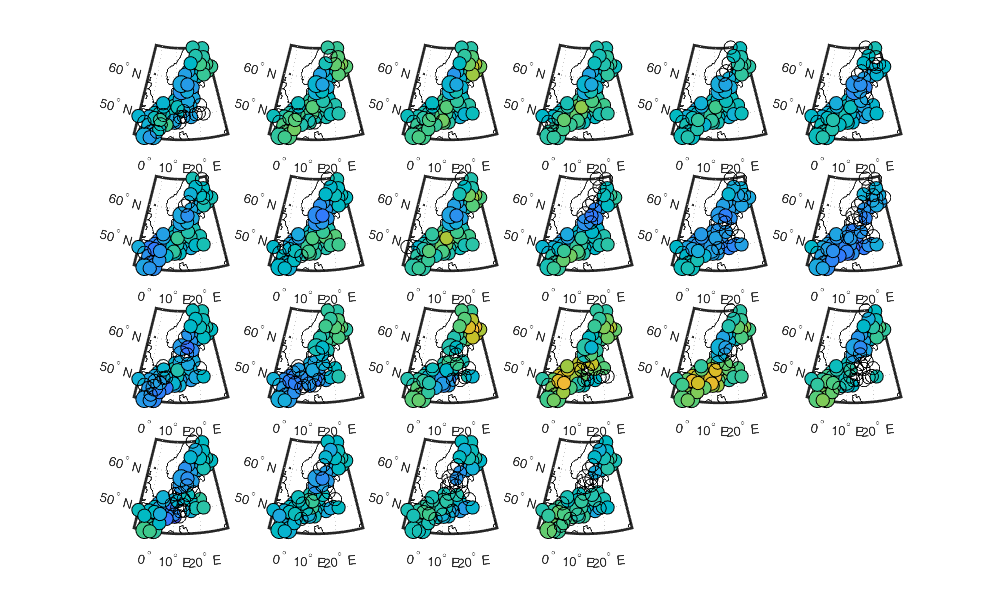

figure('position',[0 0 1000 600]); 
for i = 1:numel(uniqueDate)
    subplot(4,6,i); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  plotm(coastlat, coastlon,'k')
    scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,ampli.A_est(:,i),'filled','MarkerEdgeColor','k'); caxis(c_caxis)
end

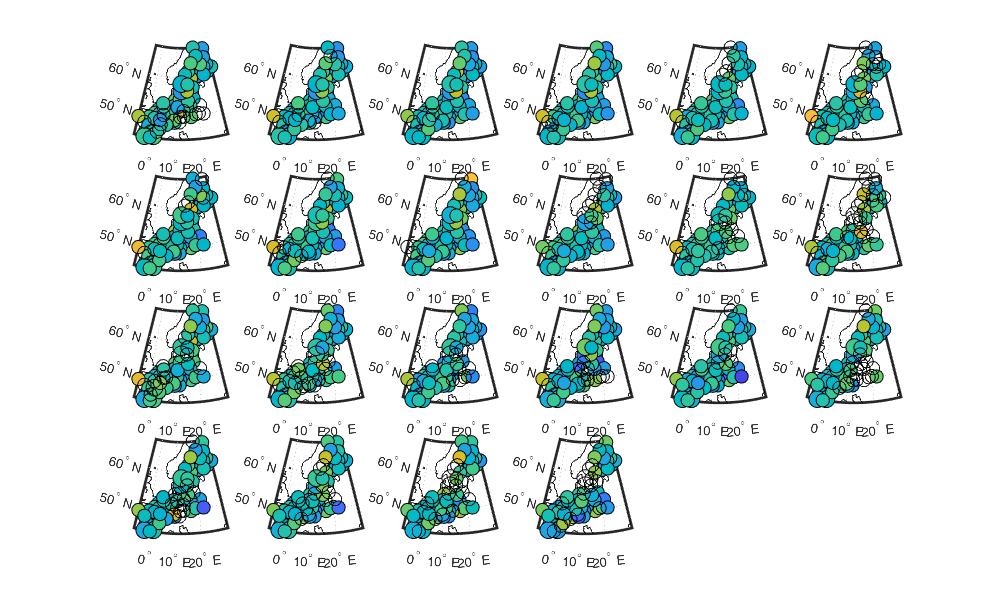

figure('position',[0 0 1000 600]); 
for i = 1:numel(uniqueDate)
    subplot(4,6,i); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  plotm(coastlat, coastlon,'k')
    scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,ampli.A_est(:,i)-ampli.A(:,i),'filled','MarkerEdgeColor','k'); caxis(c_caxis)
end

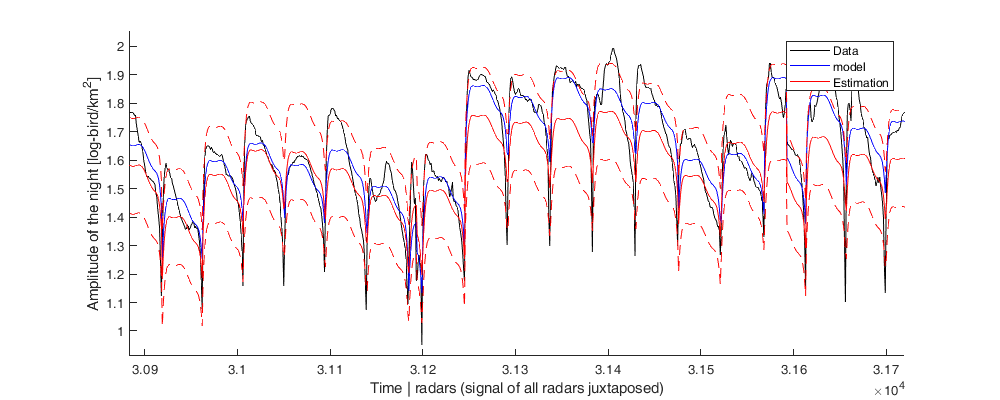

figure('position',[0 0 1000 400]); hold on; 
plot(data.denstrans,'k'); 
plot(pred3([trend.p(:);ampli.A(:);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc),'b');
plot(pred3([trend.p(:);ampli.A_est(:);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc),'r'); 
plot(pred3([trend.p(:);reshape(ampli.A_est(:)-ampli.A_sig(:),[],1);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc),'--r'); 
plot(pred3([trend.p(:);reshape(ampli.A_est(:)+ampli.A_sig(:),[],1);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc),'--r'); 

xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [log-bird/km^2]'); legend('Data','model','Estimation')

## 5. Residus

res.r = data.denstrans-pred3([trend.p(:);ampli.A(:);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc);

% A=nan(numel(dc),numel(uniqueDate));
% for i=1:numel(A)
%     id=data.dateradar==i;
%     fun = @(a) nanmean( (a*data.scoret(id)-res.r(id)).^2 );
%     A(i)=fminsearch(fun,0);
%     res.r2(id) = res.r(id)-A(i)*data.scoret(id);
% end


## 5.1 Normalization residu

Normalized the noise according to the night

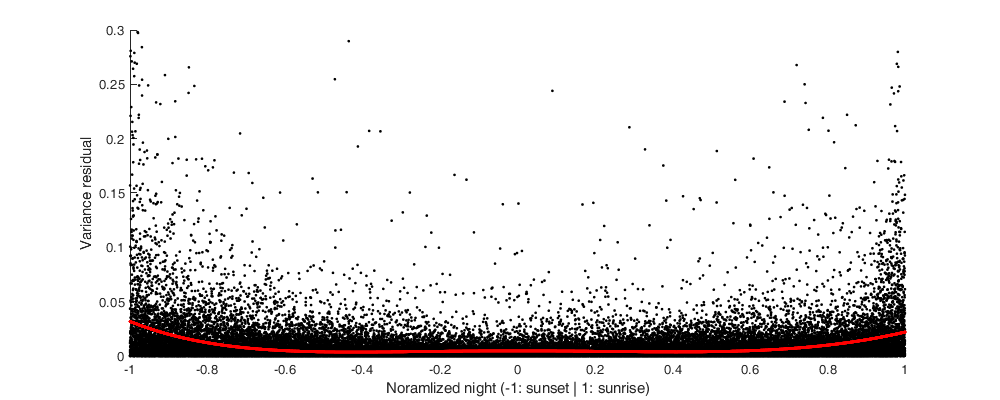

res.p = polyfit(data.scoret,res.r(:).^2,5);

figure('position',[0 0 1000 400]); hold on;
plot(data.scoret,res.r.^2,'.k'); plot(data.scoret,polyval(res.p,data.scoret),'.r'); ylim([0 .3]); 
xlabel('Noramlized night (-1: sunset | 1: sunrise)'); ylabel('Variance residual')

Normalized the residu

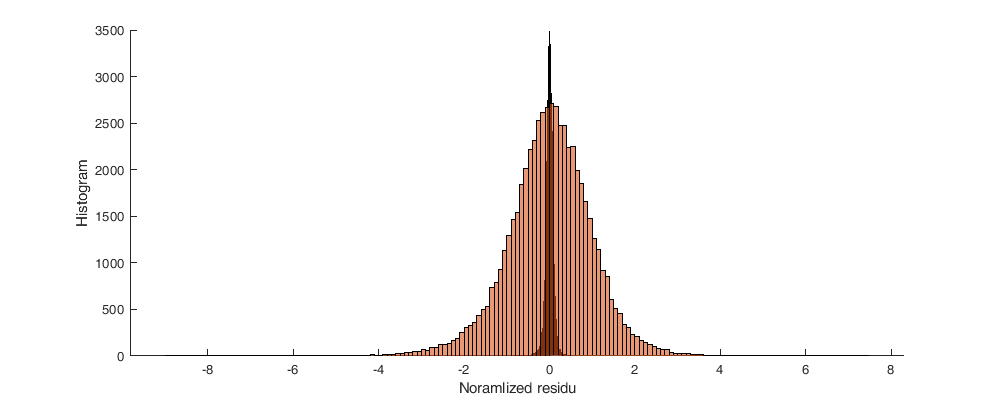

% res.ns = nscore(res.r(:)./sqrt(polyval(res.p,data.scoret)));
% res.ns.mu = nanmean(res.r(:)./sqrt(polyval(res.p,data.scoret))); =0
res.ns.std = @(scortet) std(res.r(:)./sqrt(polyval(res.p,data.scoret)))*sqrt(polyval(res.p,scortet));
res.rn = res.r./res.ns.std(data.scoret);

figure('position',[0 0 1000 400]); hold on; histogram(res.r) ; histogram(res.rn)
xlabel('Noramlized residu'); ylabel('Histogram')

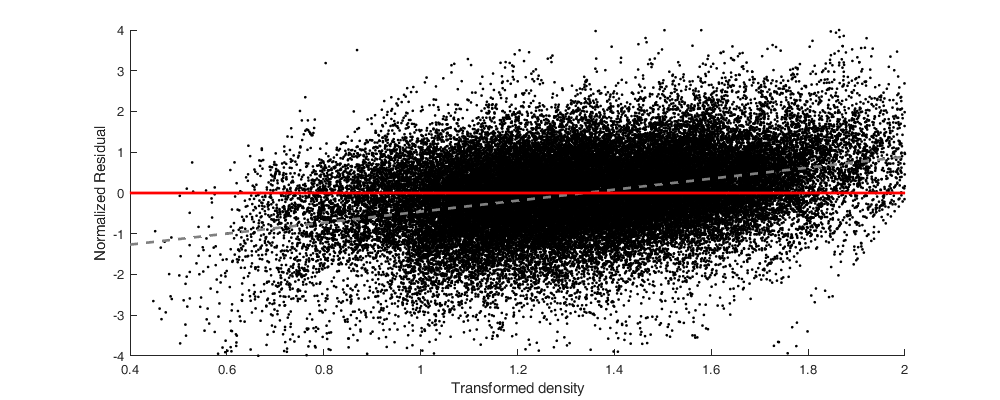

figure('position',[0 0 1000 400]); hold on; ylabel('Normalized Residual'); xlabel('Transformed density')
scatter(data.denstrans,res.rn,'.k'); 
coeffs = polyfit(data.denstrans,res.rn, 1);
plot( [.2 2.2],coeffs*[ .2 2.2; 1 1],'--','Color',[.5 .5 .5],'LineWidth',2)
plot([.2 2.2],[0 0],'r','LineWidth',2); axis([.4 2 -4 4])

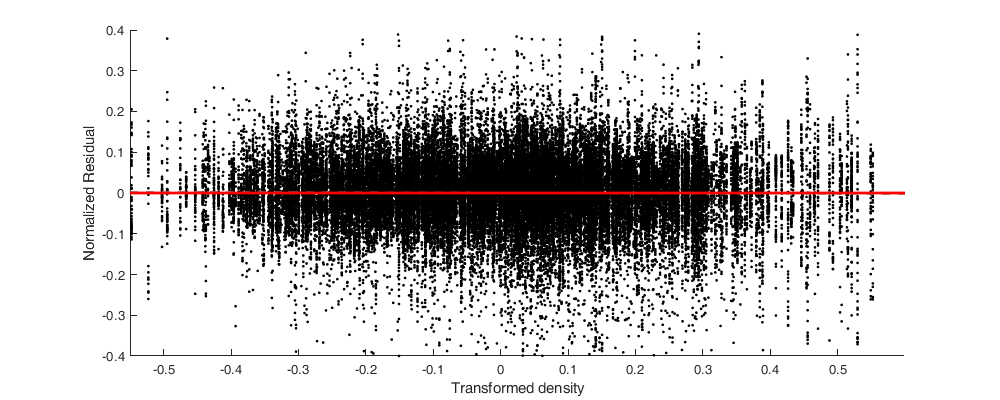

figure('position',[0 0 1000 400]); hold on; ylabel('Normalized Residual'); xlabel('Transformed density')
scatter(ampli.A(data.dateradar),res.r,'.k'); 
coeffs = polyfit(ampli.A(data.dateradar),res.r, 1);
plot( [-.8 .6],coeffs*[ -.8 .5; 1 1],'--','Color',[.5 .5 .5],'LineWidth',2)
plot([-.8 .6],[0 0],'r','LineWidth',2); axis([-.55 .6 -.4 .4])

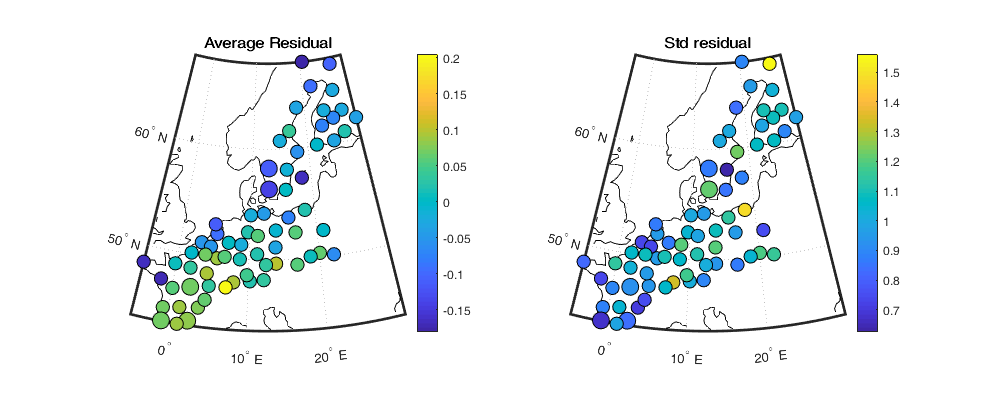

for i_r=1:numel(dc)
    res_r_m(i_r)=mean(res.rn(data.i_r==i_r));
    res_r_std(i_r)=std(res.rn(data.i_r==i_r));
end
figure('position',[0 0 1000 400]);
subplot(1,2,1); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
plotm(coastlat, coastlon,'k')
scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,res_r_m,'filled','MarkerEdgeColor','k'); title('Average Residual'); colorbar;
subplot(1,2,2); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
plotm(coastlat, coastlon,'k')
scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,res_r_std,'filled','MarkerEdgeColor','k'); title('Std residual'); colorbar;

Plot nomalized residu

Plot spatio-temporal residual. You can change resnorm by resrow or res to see the variation

h=figure(2);  
ttrend=start_date+1:1/24/4:end_date-1;
F2(numel(ttrend)-1) = struct('cdata',[],'colormap',[]); 
for i_t = 1:numel(ttrend)-1
    clf; worldmap('Europe');
    plotm(coastlat, coastlon,'k')
    id = data.time>datenum(ttrend(i_t)) & data.time<=datenum(ttrend(i_t+1));
    scatterm(data.lat(id),data.lon(id),100,res.rn(id),'filled','MarkerEdgeColor','k');
    title(datestr(ttrend(i_t))); caxis([-2 2]); drawnow;
    F2(i) = getframe(h);
end
v=VideoWriter('Density_modelInf_residu.avi');
v.FrameRate = 4;  % Default 30
v.Quality = 75;
open(v); writeVideo(v, F2); close(v);


## 5.2 Built matrix of distance

Built the matrix of distances of the data. Distence (or difference) in lattitude, longitude, time and value. 

res.D=table();
for i=1:numel(uniqueDate)
    d=table();
    
    id  = find(ismember( data.dateradar, sub2ind([numel(dc), numel(uniqueDate)],1:numel(dc),i*ones(1,numel(dc)))));

    d.Ddist = reshape(Ddist_sf(data.i_r(id),data.i_r(id)'),[],1);
    d.Dtime = reshape(squareform(pdist(data.time(id))),[],1);
    d.Did1 = repmat(id,numel(id),[]);
    d.Did2 = repelem(id,numel(id));
    
    res.D=[res.D ; d];
end

## 5.3 Empirical Variogram

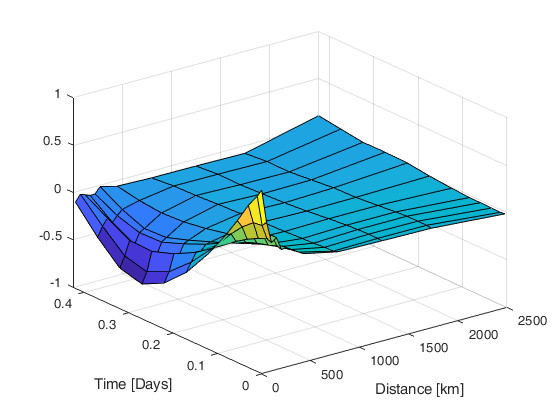

res.cov.d=[0 50 100 150 200 250 300 600 1000 1500 2000 3000];

res.cov.t=[0 .01 .02 .05 .07 .1 .15 .2 .25 .3 .35 .4 .45]; 
[res.cov.D,res.cov.T]=meshgrid(res.cov.d(1:end-1)+diff(res.cov.d)/2,res.cov.t(1:end-1)+diff(res.cov.t)/2);

res.cov.emp_grid=nan(size(res.cov.D));

for i_d=1:numel(res.cov.d)-1
    id1 = find(res.D.Ddist>=res.cov.d(i_d) & res.D.Ddist<res.cov.d(i_d+1));
    for i_t=1:numel(res.cov.t)-1
        id2 = id1(res.D.Dtime(id1)>=res.cov.t(i_t) & res.D.Dtime(id1)<res.cov.t(i_t+1));
        res.cov.emp_grid(i_t,i_d)=mean(res.rn(res.D.Did1(id2)) .* res.rn(res.D.Did2(id2)));
    end
end

Figure

figure; surf(res.cov.D,res.cov.T,res.cov.emp_grid);  xlabel('Distance [km]'); ylabel('Time [Days]');

The empirical variogram of the residu shows a very intersting effect.

[...] 

The empirical variogram of the absolute value of the residu confirms our explanation with the lowest variance.

## 5.4 Calibrate ampli.cov.parmriance 

Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>



Gneiting_fit = @(parm) parm(2).*Gneiting(res.cov.D(:),res.cov.T(:),parm(3),parm(4),parm(5),parm(6),parm(7));


ans = '0.077 0.923 206.314 0.048 1.000 0.471 0.000 '

res.cov.parm0 =[.5 .5 500 5 .5 .5 .5];
res.cov.parm_min=[0 0 0.0001 0 0 0 0 ]';
res.cov.parm_max=[nancov(res.rn) res.cov.emp_grid(1) 3000 10 1 1 1]';

rmse = @(parm) sum( ( Gneiting_fit(parm) - res.cov.emp_grid(:) ).^2 );
res.cov.parm = fmincon(rmse,res.cov.parm0,[],[],[],[],res.cov.parm_min,res.cov.parm_max,[]);% ,optimset('PlotFcn',@optimplotfval)
res.cov.parm(1) = nancov(res.rn)-res.cov.parm(2);
sprintf('%.3f ',res.cov.parm)

Figure

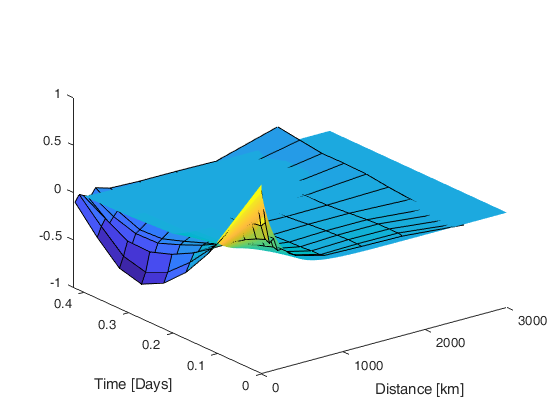

[tmpD,tmpT] = meshgrid(res.cov.d(1):1:res.cov.d(end),res.cov.t(1):0.1:res.cov.t(end));
tmpCOV=res.cov.parm(2).*Gneiting(tmpD(:), tmpT(:), res.cov.parm(3), res.cov.parm(4), res.cov.parm(5), res.cov.parm(6), res.cov.parm(7));

tmpCOV=reshape(tmpCOV,size(tmpD,1),size(tmpD,2));
tmpCOV(1)=tmpCOV(1)+res.cov.parm(1);
figure; hold on;
s=surf(tmpD,tmpT,tmpCOV);
surf(res.cov.D,res.cov.T,res.cov.emp_grid);  xlabel('Distance [km]'); ylabel('Time [Days]');
s.EdgeColor='none'; view(3)

## 5.5 Kriging residual

res.cov.C = res.cov.parm(2).*Gneiting(res.D.Ddist, res.D.Dtime, res.cov.parm(3), res.cov.parm(4), res.cov.parm(5), res.cov.parm(6), res.cov.parm(7));
res.cov.C = sparse(res.D.Did1,res.D.Did2,res.cov.C);
res.cov.C = res.cov.C + spdiags(repmat(res.cov.parm(1),size(res.cov.C,1),1),0,size(res.cov.C,1),size(res.cov.C,2));

res.rn_est=nan(size(res.rn));
res.rn_sig=nan(size(res.rn));

for i_d=1:numel(uniqueDate)
    neigh  = find(ismember( data.dateradar, sub2ind([numel(dc), numel(uniqueDate)],1:numel(dc),i_d*ones(1,numel(dc)))));

    for i_s=1:numel(neigh)
        
        neigh_s = neigh(data.dateradar(neigh)~=data.dateradar(neigh(i_s)));
        Cab = full(res.cov.C(neigh_s,neigh(i_s)));
        neigh_s=neigh_s(Cab>.1);

            % Simple
            lambda = res.cov.C(neigh_s,neigh_s) \ res.cov.C(neigh_s,neigh(i_s));
            res.rn_est(neigh(i_s)) =  lambda' * res.rn(neigh_s);
            res.rn_sig(neigh(i_s)) = sqrt(res.cov.parm(1) + res.cov.parm(2) - lambda' * res.cov.C(neigh_s,neigh(i_s)));
            
            % Ordinary
            % lambda = [Caa ones(size(Caa,1),1); ones(1,size(Caa,1)) 0] \ [ Cab ; 1];
            % res.rn_est(i) =  lambda(1:end-1)' * res.rn(neigh);
            % res.rn_sig(i) = res.cov.parm(1) + res.cov.parm(2) - lambda(1:end-1)' * Cab - lambda(end);
            
            % figure; hold on;
            % scatter3(data.lon(i),data.lat(i),data.time(i),'r','filled')
            % % scatter3(data.lon(neigh),data.lat(neigh),data.time(neigh),[],Cab,'filled')
            %  scatter3(data.lon(neigh),data.lat(neigh),data.time(neigh),[],lambda,'filled')
    end
end

Figure

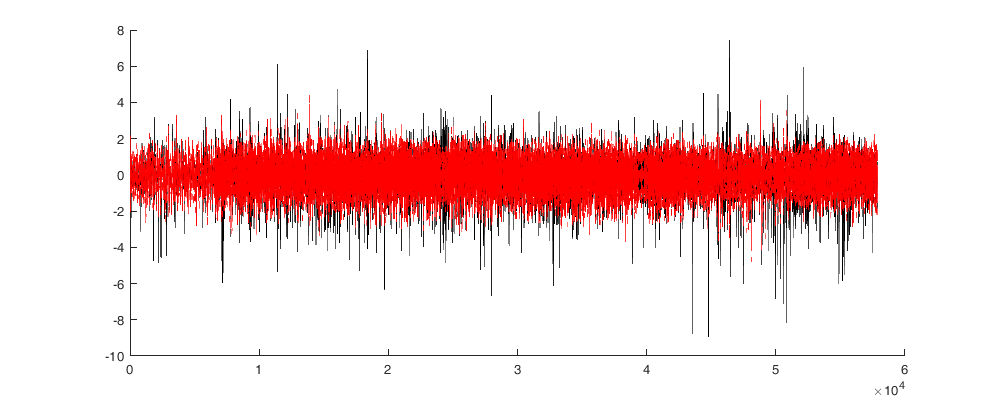

figure('position',[0 0 1000 400]); hold on;
plot(res.rn,'k');
plot(res.rn_est,'r')

plot(res.rn_est-res.rn_sig,'--r')
plot(res.rn_est+res.rn_sig,'--r')

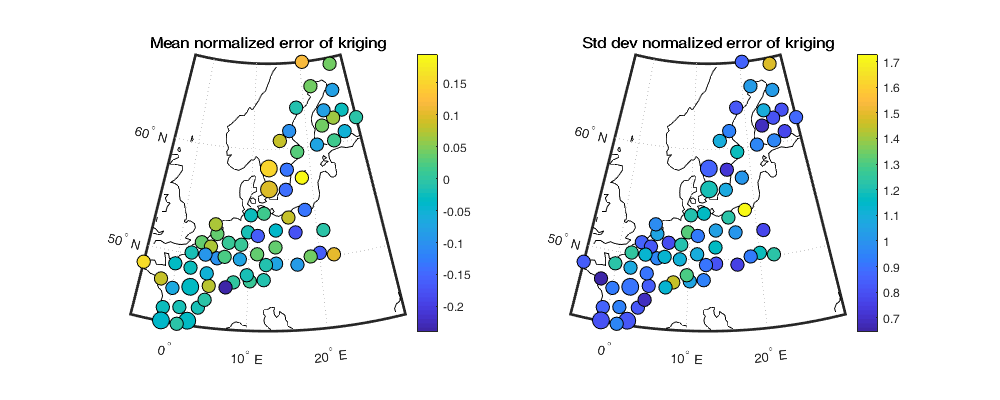


for i_r=1:numel(dc)
    res_err_avg(i_r) = mean((res.rn_est(data.i_r==i_r)-res.rn(data.i_r==i_r))./res.rn_sig(data.i_r==i_r));
    res_err_std(i_r) = std((res.rn_est(data.i_r==i_r)-res.rn(data.i_r==i_r))./res.rn_sig(data.i_r==i_r));
end

figure('position',[0 0 1000 400]);  
subplot(1,2,1); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
plotm(coastlat, coastlon,'k')
scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,res_err_avg,'filled','MarkerEdgeColor','k'); title('Mean normalized error of kriging'); colorbar;
subplot(1,2,2); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
plotm(coastlat, coastlon,'k')

scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,res_err_std,'filled','MarkerEdgeColor','k'); title('Std dev normalized error of kriging'); colorbar;

## 5.6 Back Normalized

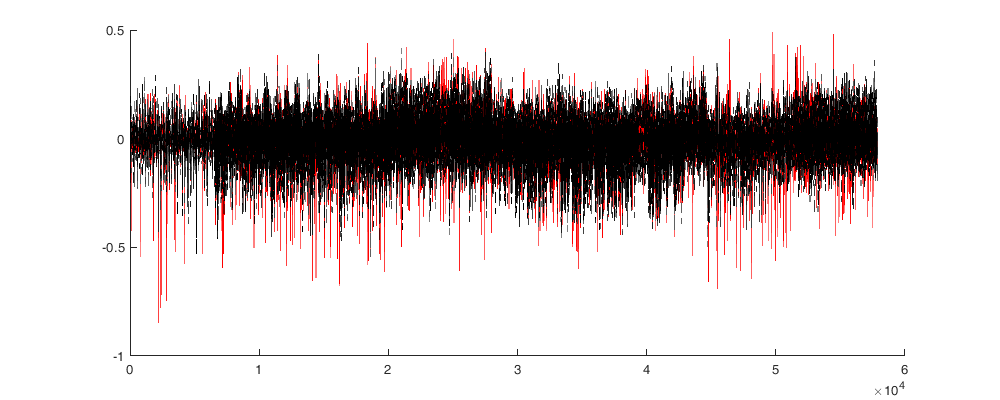

res.r_est = res.rn_est.*res.ns.std(data.scoret);
res.r_sig = sqrt(res.rn_sig.^2.*res.ns.std(data.scoret).^2);
%res.r_est = res.ns.inverse(bsxfun(@times,sqrt(polyval(res.p,data.scoret)),bsxfun(@plus , res.rn_est, res.rn_sig*(-3:3))));

figure('position',[0 0 1000 400]); hold on;
plot(res.r,'r')
plot(res.r_est,'-k')
plot(res.r_est-res.r_sig,'--k')
plot(res.r_est+res.r_sig,'--k')

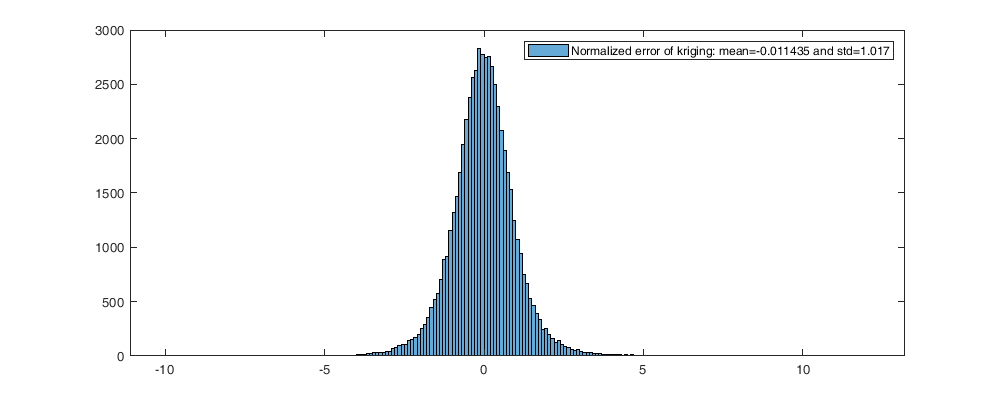

err_norm = (res.r_est-res.r)./(res.r_sig);
figure('position',[0 0 1000 400]); histogram( err_norm );
legend(['Normalized error of kriging: mean=' num2str(mean(err_norm)) ' and std=' num2str(std(err_norm))]);

## 6. Assemble the estimation

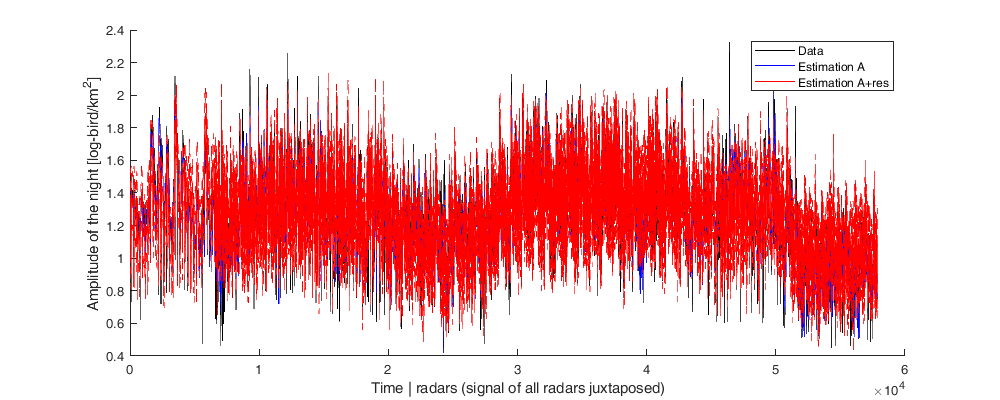

data.denstrans_est = pred3([trend.p(:);ampli.A_est(:);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc)+res.r_est;
data.denstrans_sig = sqrt(ampli.A_sig(data.dateradar).^2 + res.r_sig.^2);
data.dens_est = (data.denstrans_est).^(1/pow_a);

figure('position',[0 0 1000 400]); hold on;
plot(data.denstrans,'k');
plot(pred3([trend.p(:);ampli.A(:);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc),'b');
plot(data.denstrans_est,'r');
plot(data.denstrans_est-data.denstrans_sig ,'--r');
plot(data.denstrans_est+data.denstrans_sig ,'--r');
xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [log-bird/km^2]'); legend('Data','Estimation A','Estimation A+res')

## Cross-validation

Overall score

sqrt(mean( (pred3([trend.p(:);ampli.A_est(:);curve.p(:)],numel(dc),numel(uniqueDate),curve.nb_poly,data,dc)-data.denstrans ).^2 ))

ans = 0.1504

sqrt(mean( (data.denstrans_est-data.denstrans ).^2 ))

ans = 0.1410

sqrt(mean( (data.dens_est-data.dens ).^2 ))

ans = 32.5973

Error

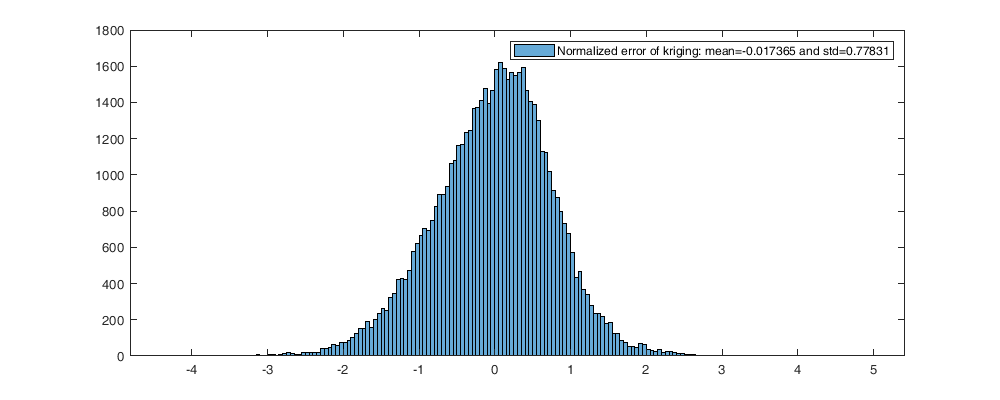

err_norm = (data.denstrans-data.denstrans_est)./data.denstrans_sig;
figure('position',[0 0 1000 400]); histogram( err_norm );
legend(['Normalized error of kriging: mean=' num2str(mean(err_norm)) ' and std=' num2str(std(err_norm))]);

figure('position',[0 0 1000 400]);
plot(data.dens_est,data.dens,'.k')


## Comparing to simple interpoloation

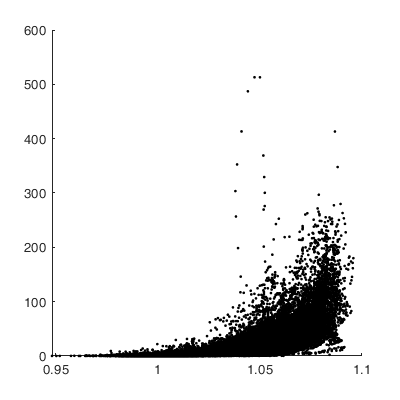

data_interp = load('data/Density_Interpol.mat','data');

figure('position',[0 0 400 400]); hold on;
scatter(data.dens_est,data.dens,'.k')

scatter(data_interp.data.dens_pred,data.dens,'.g')

Error using scatter (line 61)
X and Y must be vectors of the same length.

plot([0 max(data.dens)],[0 max(data.dens)],'-r','LineWidth',2);
axis equal;xlabel('Estimate value'); ylabel('True value');

## 7. Save


save('data/Density_modelInf.mat','data','trend','ampli','curve','res','pow_a','-v7.3')
% load('data/Density_modelInf.mat')

% writetable(data,'data/Density_modelInf_data.csv')